a = 1e-6;
N = 100; %discretize in real space
Nmode = 5;
nmode = 2;
kx_step = 0.05*pi/a; %discretize in reciprocal space
ky_step = 0.05*pi/a;
kx_start = pi/a-0.5*pi/a;
kx_end = pi/a+0.55*pi/a;
ky_start = pi/a-0.5*pi/a;
ky_end = pi/a+0.55*pi/a;

Nkx = (kx_end-kx_start)/kx_step+1;
Nky = (ky_end-ky_start)/ky_step+1;
delta_x = a/N;
delta_y = a/N;
delta_S = delta_x*delta_y;
xx = 0:delta_x:a;
yy = 0:delta_y:a;
coord_mat = zeros(2,N*N);
for i = 1:N
    for j = 1:N
        coord_mat(:,j+i*(N-1)) = [xx(j)+0.5*delta_x;yy(i)+0.5*delta_y];
    end
end
%Hx = mphinterp(model,'ewfd.Hx','coord',coord_mat);
%Hy = mphinterp(model,'ewfd.Hy','coord',coord_mat);
%Hz = mphinterp(model,'ewfd.Hz','coord',coord_mat);
%Ex = mphinterp(model,'ewfd.Ex','coord',coord_mat);
%Ey = mphinterp(model,'ewfd.Ey','coord',coord_mat);
Ez = mphinterp(model,'ewfd.Ez','coord',coord_mat);

eps = mphinterp(model,'ewfd.epsilonrxx','coord',coord_mat);


sum = 0;
berry = zeros(Nky-1,Nkx-1);
for i = 1:(Nkx-1)
    kx = kx_start + (i-1)*kx_step;
    for j = 1:(Nky-1)
        ky = ky_start + (j-1)*ky_step;
        %cur = berry_curvature(Hx,Hy,i,j,nmode,Nky,Nmode,delta_S);
        %cur = berry_curvature2(Hz,i,j,nmode,Nky,Nmode,delta_S,kx,ky,coord_mat);
        cur = berry_curvature3(Ez,eps,i,j,nmode,Nky,Nmode,delta_S);
        sum = sum + cur;
        cur = cur/(kx_step*ky_step)/(a^2/4/pi^2);
        berry(j,i) = cur;
    end
end
sum

sum = -4.9692 + 0.0000i

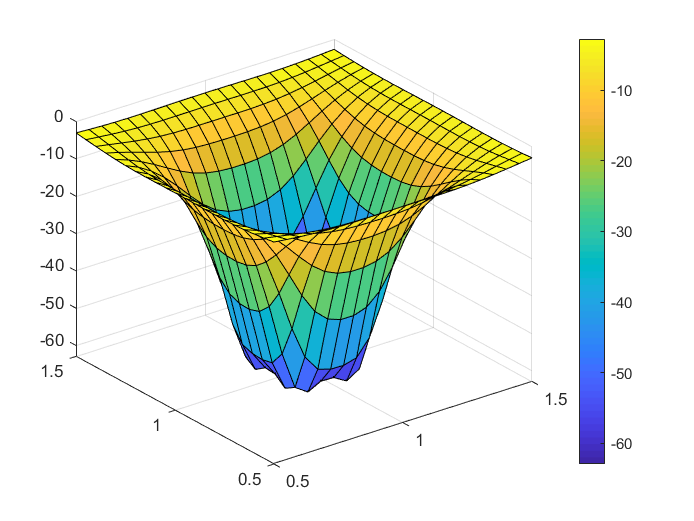


[X,Y] = meshgrid((kx_start:kx_step:(kx_end-kx_step))/(pi/a),(ky_start:ky_step:(ky_end-ky_step))/(pi/a));
Z = real(berry);
surf(X,Y,Z);
colorbar